# EKF - MHE Unconstrained Performance Comparison

clc
clear
close all

## Load Estimated States & Measured Data

rng('default')

addpath("simulation");
addpath("Optimization/UncOpt");
addpath("Optimization/ConsOpt");
addpath("simulation/SimulationData");

Urban = 0; % by default set it to 0, constrained problem only in highway
real_meas = 0; 
max_time = 25;
min_time = 0.5;
Con = 0; % set to 1 if dealing with a constrained estimation problem

[ymeas_camera,ymeas_radar,N,time_vec,GT_state,min_index,max_index,~,~] = get_meas(Con,Urban,real_meas,min_time,max_time);

z_est_EKF = cell2mat(struct2cell(load('z_est_EKF.mat')));
z_est_Con = cell2mat(struct2cell(load('z_est_MHE_Con.mat')));
z_est_MHE = cell2mat(struct2cell(load('z_est_MHE.mat')));

## Plot Results

% indexes to limit x axes on plots
fine = 21;
inizio = 13;

### Relative Position

#### $x$ - Coordinate

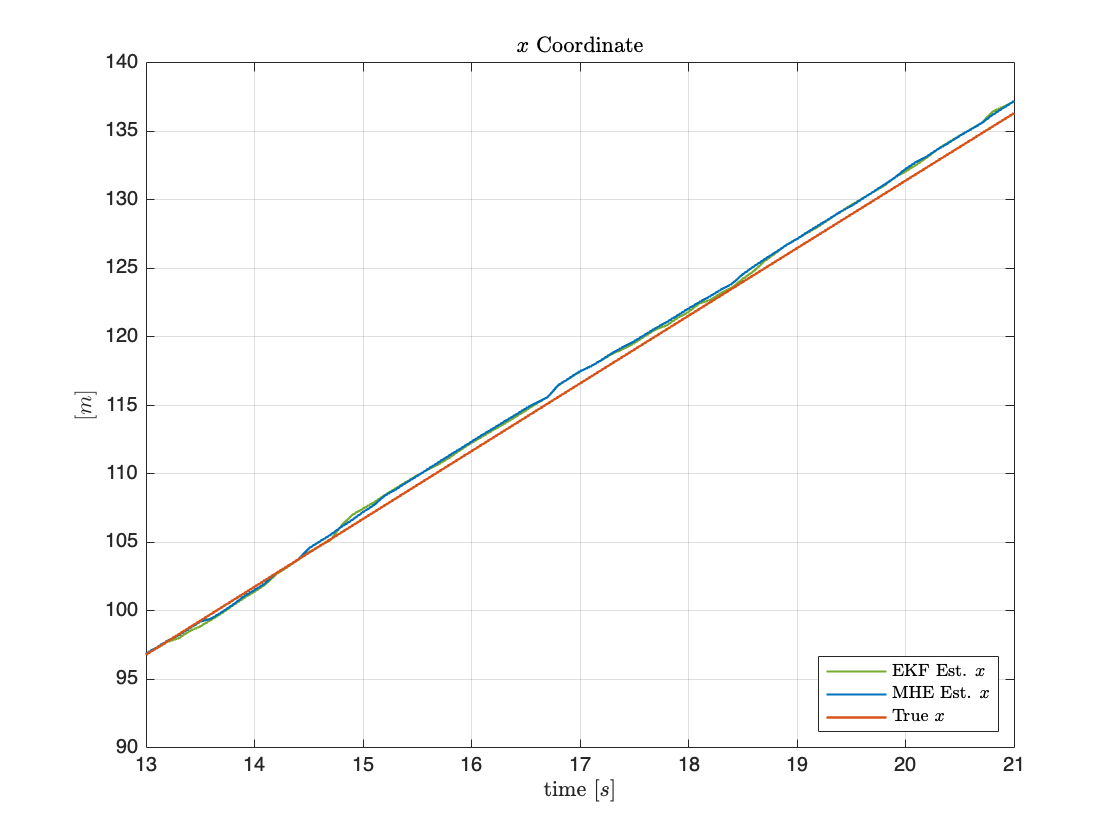

figure;
% plot(time_vec,z_est_EKF(1,:),"LineWidth",1.1,"Color","#77AC30"), hold on,grid on
plot(time_vec,z_est_Con(1,:),"LineWidth",1.1,"Color","#77AC30"), hold on,grid on
plot(time_vec,z_est_MHE(1,:),"LineWidth",1.1,"Color","#0072BD"), hold on
plot(time_vec,GT_state(:,1),"LineWidth",1.2,"Color","#D95319"), hold on
title('$x$ Coordinate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m]$','Interpreter','latex')
ylim([90 140]);
xlim([inizio fine]);
legend('EKF Est. $x$','MHE Est. $x$','True $x$','Interpreter','latex','Location','southeast')

#### $y$ - Coordinate

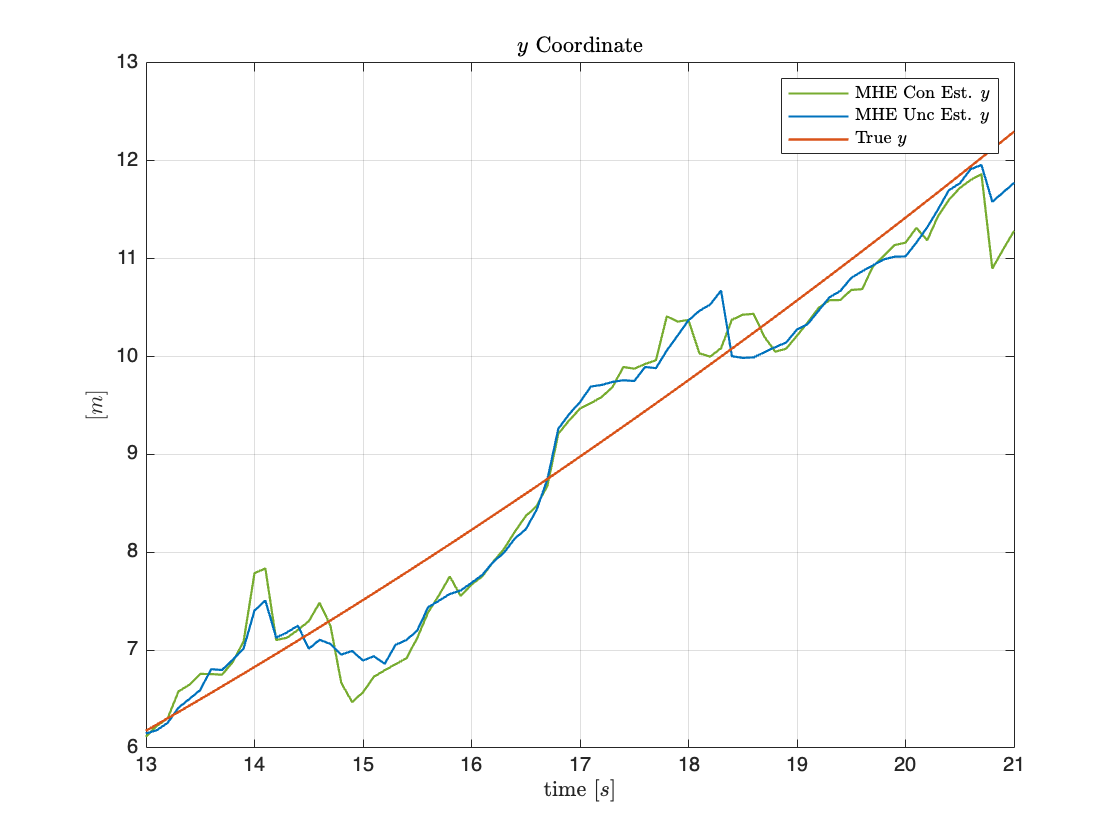

figure;
plot(time_vec,z_est_Con(2,:),"LineWidth",1.1,"Color","#77AC30"), hold on,grid on
plot(time_vec,z_est_MHE(2,:),"LineWidth",1.1,"Color","#0072BD"), hold on,grid on
plot(time_vec,GT_state(:,2),"LineWidth",1.2,"Color","#D95319"), hold on
title('$y$ Coordinate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m]$','Interpreter','latex')
legend('MHE Con Est. $y$','MHE Unc Est. $y$','True $y$','Interpreter','latex')
xlim([inizio fine]);

### Velocities

#### 
$$v_x$$


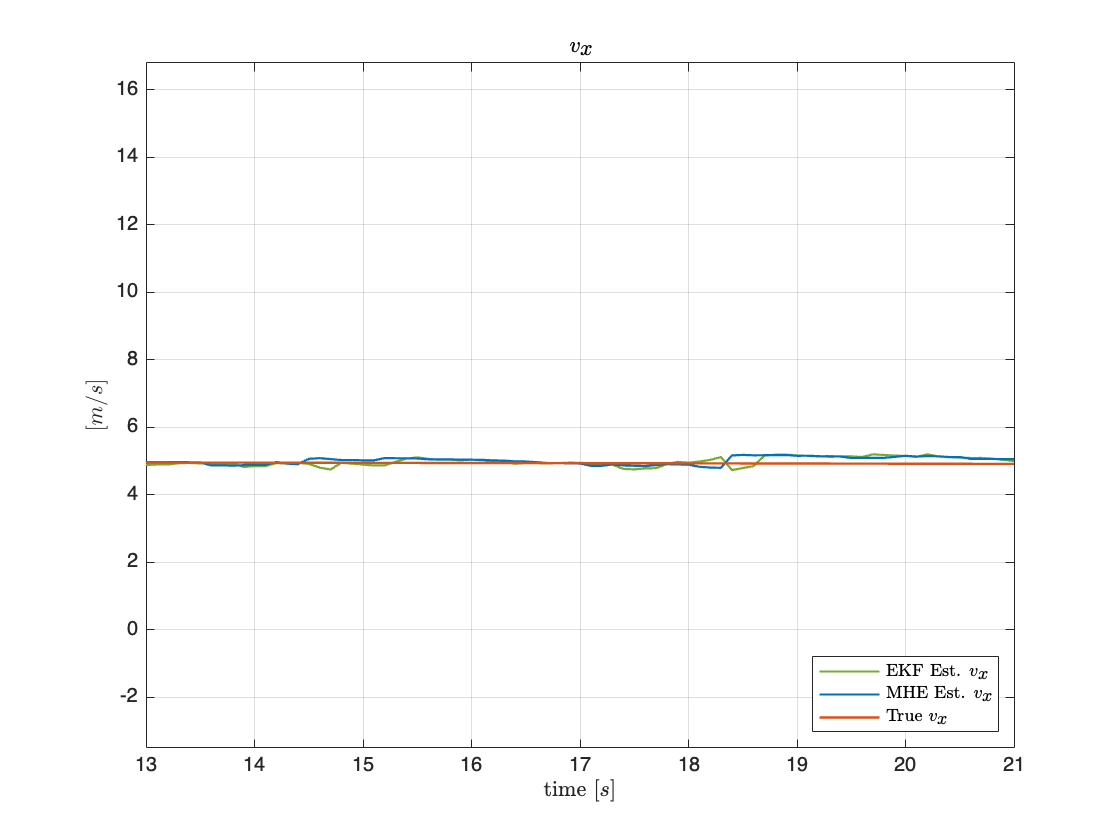

figure;
plot(time_vec,z_est_Con(3,:),"LineWidth",1.1,"Color","#77AC30"), hold on,grid on
plot(time_vec,z_est_MHE(3,:),"LineWidth",1.1,"Color","#0072BD"), hold on,grid on
plot(time_vec,GT_state(:,3),"LineWidth",1.2,"Color","#D95319"), hold on
title('$v_x$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m/s]$','Interpreter','latex')
legend('EKF Est. $v_x$','MHE Est. $v_x$','True $v_x$','Interpreter','latex','Location','southeast')
ylim([-3.5, 16.8])
xlim([inizio fine]);

#### 
$$v_y$$


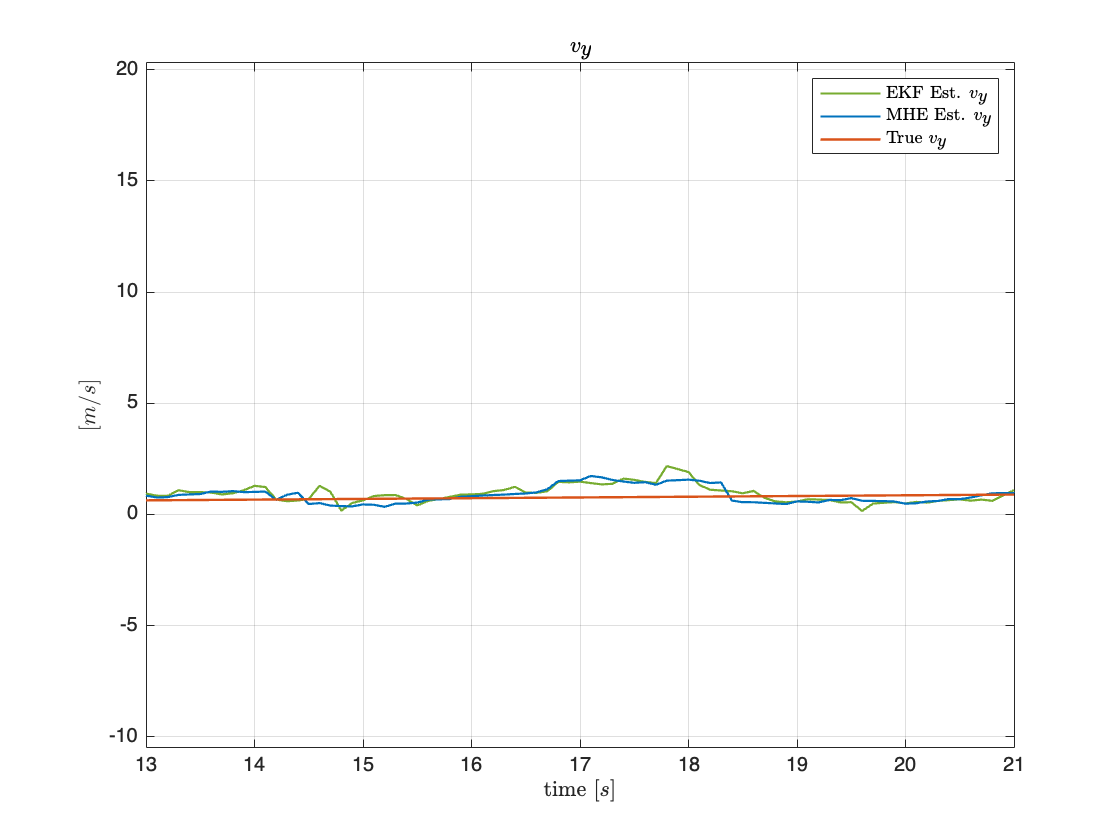

figure;
plot(time_vec,z_est_Con(4,:),"LineWidth",1.1,"Color","#77AC30"), hold on,grid on
plot(time_vec,z_est_MHE(4,:),"LineWidth",1.1,"Color","#0072BD"), hold on,grid on
plot(time_vec,GT_state(:,4),"LineWidth",1.2,"Color","#D95319"), hold on
title('$v_y$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m/s]$','Interpreter','latex')
legend('EKF Est. $v_y$','MHE Est. $v_y$','True $v_y$','Interpreter','latex')
ylim([-10.5 20.3])
xlim([inizio fine]);

#### Yaw Rate

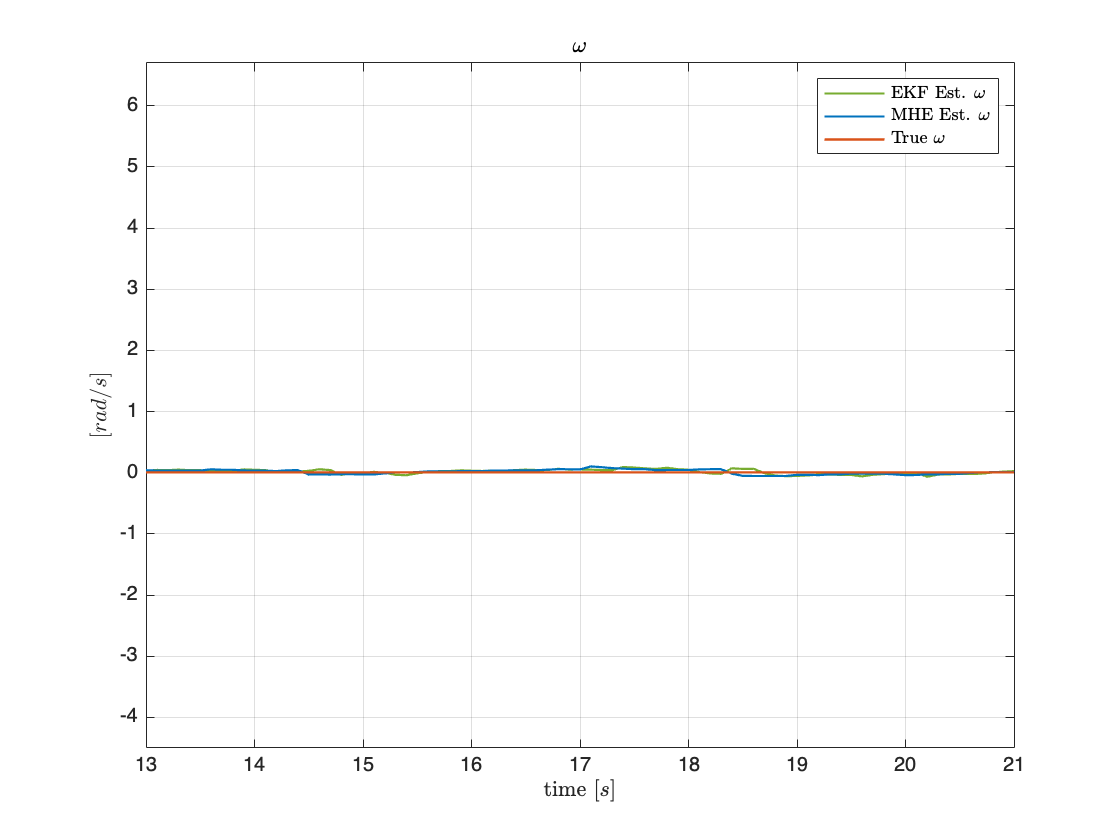

figure;
plot(time_vec,z_est_Con(5,:),"LineWidth",1.1,"Color","#77AC30"), hold on,grid on
plot(time_vec,z_est_MHE(5,:),"LineWidth",1.1,"Color","#0072BD"), hold on,grid on
plot(time_vec,GT_state(:,5),"LineWidth",1.2,"Color","#D95319")
title('$\omega$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[rad/s]$','Interpreter','latex')
legend('EKF Est. $\omega$','MHE Est. $\omega$','True $\omega$','Interpreter','latex')
ylim([-4.5 6.7])
xlim([inizio fine]);